
% Plan: Given a ship hull, find variables to set. Initialize these, then
% write algorithm to alter other variables and minimize r^2
% find set of points

boat = boat1(); % change based on target boat

% set bounds based on constraints
Dd = boat.Dd; 
Bd = boat.Bd; 
lb = [0, 0, 0, 0, 0, -Bd, -Bd, 0, 0, -Dd, -Dd, -Dd, -Dd,-Dd]; 
ub = [Bd*2, Dd, 90, Bd, Bd, Bd, Bd, Dd, 1, Dd, Dd, Dd, Dd, Dd];
Aineq = []; 
bineq = []; 
Aeq = []; 
beq= [];

% create target function
FitFcn= @(Bs, WL, Beta, Rc, Rk, Abow, Bbow, BK_z, Kappa, Adel, Bdel, Adrft, Bdrft, Cdrft) -rsqval(Bs, WL, Beta, Rc, Rk, Abow, Bbow, BK_z, Kappa, Adel, Bdel, Adrft, Bdrft, Cdrft);
nvars = 14; 
% find optimal parameters with genetic algorithm
[x, fval] = ga(@(x) FitFcn(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), x(9), x(10), x(11), x(12), x(13), x(14)), nvars, Aineq, bineq, Aeq, beq, lb, ub)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     4.7335    0.9704   88.2353    2.5366    0.6827   -1.3602   -2.5209    0.1047    0.2540   -0.4538   -0.3193   -1.8267    0.3265    1.4198


fval = -0.6324


% find new y vals from python script
boat = boat1();
xs = boat.points(:,1); 
ys = boat.points(:,2); 
zs = boat.points(:,3); 

params = [boat.LOA, boat.Lb, boat.Ls, boat.Bd, boat.Dd, x(1), x(2), boat.Bc, boat.Dc, x(3:36)]

params =    10.3000    3.6000    1.8000    2.7300    2.1400    4.7335    0.9704    2.3700    9.6700   88.2353    2.5366    0.6827   -1.3602   -2.5209    0.1047    0.2540   -0.4538   -0.3193   -1.8267    0.3265    1.4198


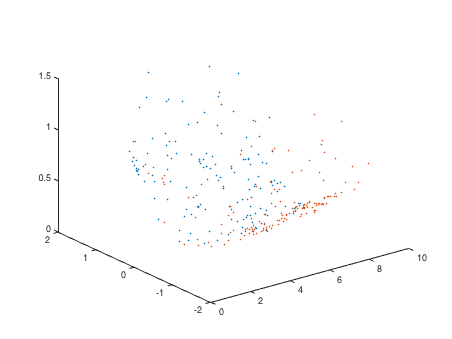


new_ys = pyrunfile("findpoints.py","yval",x_vals = xs, z_vals= zs, Vec = params);
new_ys = cell(new_ys); 
new_ys = [new_ys{:}]';

x = xs(new_ys~= -1);
y = new_ys(new_ys ~= -1);
z = zs(new_ys ~=-1);

plot3([xs xs], [ys -ys], [zs zs], '.'); % target hull plot

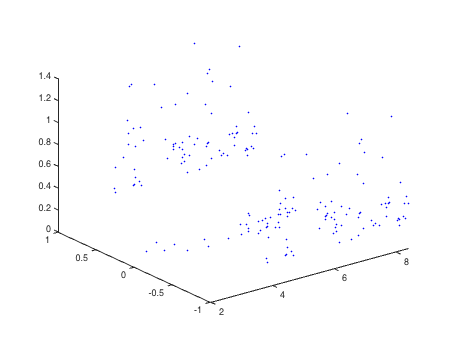

plot3([x x], [y y*-1], [z z], 'b.') % new hull plot

function new_pts = findpts(Bs, WL, Beta, Rc, Rk, Abow, Bbow, BK_z, Kappa, Adel, Bdel, Adrft, Bdrft, Cdrft)
    boat = boat1(); %% change based on target boat
    params = [boat.LOA, boat.Lb, boat.Ls, boat.Bd, boat.Dd, Bs, WL, boat.Bc, boat.Dc, Beta, Rc, Rk, Abow, Bbow, BK_z, Kappa, Adel, Bdel, Adrft, Bdrft, Cdrft];
    xs = boat.points(:,1); 
    ys = boat.points(:,2); 
    zs = boat.points(:,3); 
    chamfer = pyrunfile("PointGen.py", "pts", Vec = params target_cloud = [xs; ys; zs;]); 

end


function [new_x new_y new_z ynew] = yvals(xs, ys, zs, yvals) 
    ynew = yvals;
    new_y = ys(ynew~= -1);
    new_x = xs(ynew~= -1);
    new_z = zs(ynew~=-1);
    ynew = ynew(ynew~= -1); 
end



